# LAB1

## Implementing Spiking Neurons using Izhikevich's Model

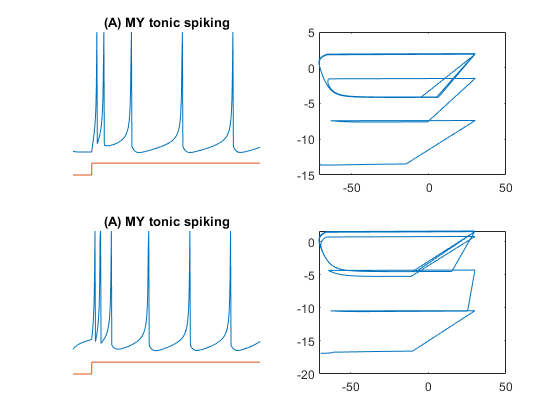

subplot(2,2,1) 
a=0.02; b=0.2;  c=-65;  d=6;
x=-70; y=b*V;
VV1=[];  uu1=[];
tau = 0.25; tspan = 0:tau:100;
T1=tspan(end)/10;
for t=tspan
    if (t>T1) 
        I=14;
    else
        I=0;
    end;
    [tmp1,tmp2,next]=Fourth_Order_Runge_Method_Izhikevich_Model(x,y,tau,a,b,c,d,I);
    VV1(end+1)=tmp1;
    uu1(end+1)=tmp2;
    x=next;
    y=tmp2;
end;
% plot(tspan,VV,[0 T1 T1 max(tspan)],-90+[0 0 10 10]);
% axis([0 max(tspan) -90 30])
% axis off;
% title('(A) tonic spiking');

plot(tspan,VV1,[0 T1 T1 max(tspan)],-90+[0 0 10 10]);
axis([0 max(tspan) -90 30])
axis off;
title('(A) MY tonic spiking');
subplot(2,2,2) 
plot(VV1,uu1)
subplot(2,2,3) 

a=0.02; b=0.25;  c=-65;  d=6;
x=-70; y=b*V;
VV1=[];  uu1=[];
tau = 0.25; tspan = 0:tau:100;
T1=tspan(end)/10;
for t=tspan
    if (t>T1) 
        I=14;
    else
        I=0;
    end;
    [tmp1,tmp2,next]=Fourth_Order_Runge_Method_Izhikevich_Model(x,y,tau,a,b,c,d,I);
    VV1(end+1)=tmp1;
    uu1(end+1)=tmp2;
    x=next;
    y=tmp2;
end;
% plot(tspan,VV,[0 T1 T1 max(tspan)],-90+[0 0 10 10]);
% axis([0 max(tspan) -90 30])
% axis off;
% title('(A) tonic spiking');

plot(tspan,VV1,[0 T1 T1 max(tspan)],-90+[0 0 10 10]);
axis([0 max(tspan) -90 30])
axis off;
title('(A) MY tonic spiking');
subplot(2,2,4) 
plot(VV1,uu1)


%sf2 = @(inputs) subFcn2(inputs)